mdl_puma560;

p560;
disp(p560);

  SerialLink with properties:

            name: 'Puma 560'
         gravity: [3×1 double]
            base: [1×1 SE3]
            tool: [1×1 SE3]
    manufacturer: 'Unimation'
         comment: 'viscous friction; params of 8/95'
         plotopt: []
            fast: 0
       interface: []
       ikineType: 'puma'
           trail: []
           movie: []
           delay: []
            loop: []
         model3d: 'UNIMATE/puma560'
           faces: []
          points: []
       plotopt3d: []
               n: 6
           links: [1×6 Revolute]
               T: []
             mdh: 0
          config: 'RRRRRR'
          offset: [0 0 0 0 0 0]
            qlim: [6×2 double]
               d: [0 0 0.1500 0.4318 0 0]
               a: [0 0.4318 0.0203 0 0 0]
           alpha: [1.5708 0 -1.5708 1.5708 -1.5708 0]
           theta: []
              qz: [0 0 0 0 0 0]
              qs: [0 0 -1.5708 0 0 0]
              qr: [0

% 3.3

disp('Zero angle configuration:');

Zero angle configuration:


qz = p560.qz;
disp(p560.qz);

     0     0     0     0     0     0



disp('Ready configuration:');

Ready configuration:


qr = p560.qr;
disp(p560.qr);

         0    1.5708   -1.5708         0         0         0



disp('Stretch configuration:');

Stretch configuration:


qs = p560.qs;
disp(p560.qs);

         0         0   -1.5708         0         0         0



disp('Nominal configuration:');

Nominal configuration:


qn = p560.qn;
disp(p560.qn);

         0    0.7854    3.1416         0    0.7854         0



% 3.4

p560.tool = SE3(0, 0, 0.2);

%3.5

T_zero = p560.fkine(qz);  % Forward kinematics for zero angle configuration
T_ready = p560.fkine(qr);  % Forward kinematics for ready configuration
T_stretch = p560.fkine(qs);  % Forward kinematics for stretch configuration
T_nominal = p560.fkine(qn);  % Forward kinematics for nominal configuration

disp('Position and Orientation (TCP) for Zero Angle:');

Position and Orientation (TCP) for Zero Angle:


disp(T_zero);

    1         0         0    0.4521
    0         1         0     -0.15
    0         0         1    0.6318
    0         0         0         1


disp('Position and Orientation (TCP) for Ready:');

Position and Orientation (TCP) for Ready:


disp(T_ready);

    1         0         0    0.0203
    0         1         0     -0.15
    0         0         1     1.064
    0         0         0         1


disp('Position and Orientation (TCP) for Stretch:');

Position and Orientation (TCP) for Stretch:


disp(T_stretch);

     6.123e-17 6.123e-17         1     1.064
    -6.123e-17         1-6.123e-17   -0.1501
            -1-6.123e-17 6.123e-17   -0.0203
             0         0         0         1


disp('Position and Orientation (TCP) for Nominal:');

Position and Orientation (TCP) for Nominal:


disp(T_nominal);

    -2.776e-16 6.123e-17         1    0.7963
    -6.123e-17         1-6.123e-17   -0.1501
            -1-6.123e-17-2.776e-16  -0.01435
             0         0         0         1


%3.6
p560.plot3d(qz);  % Visualization for zero angle configuration

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


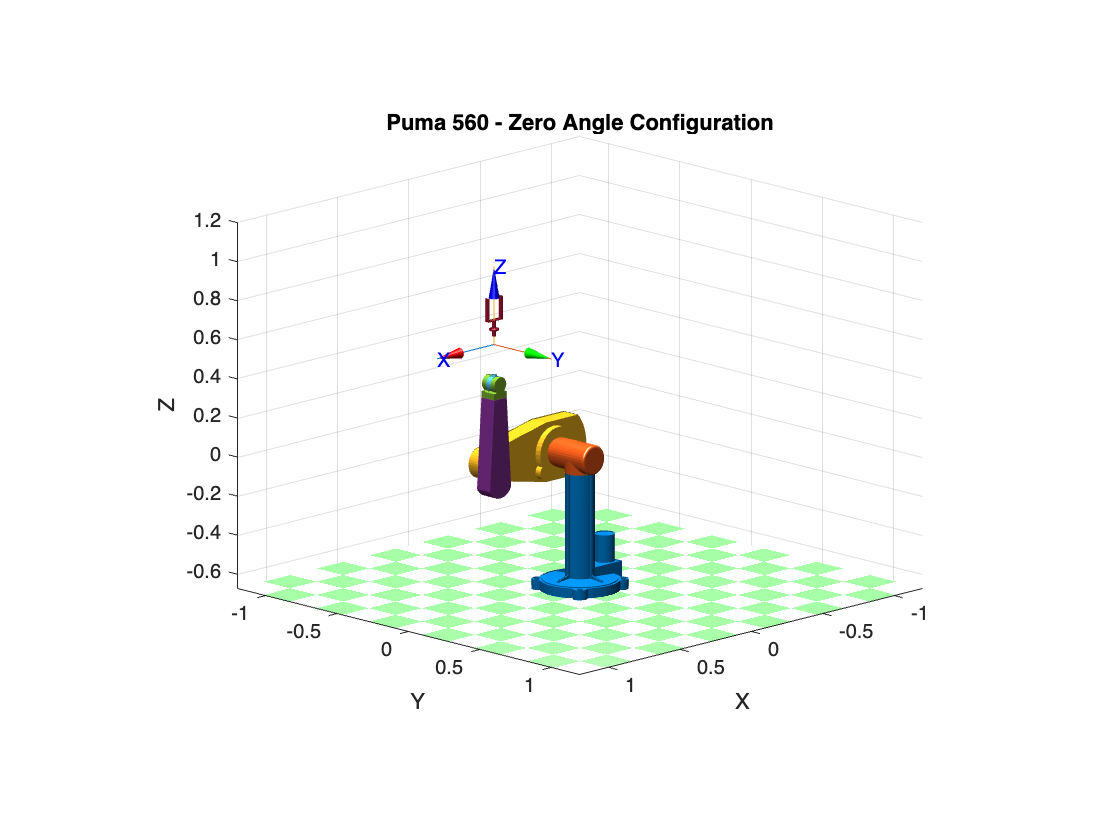

hold on;
title('Puma 560 - Zero Angle Configuration');

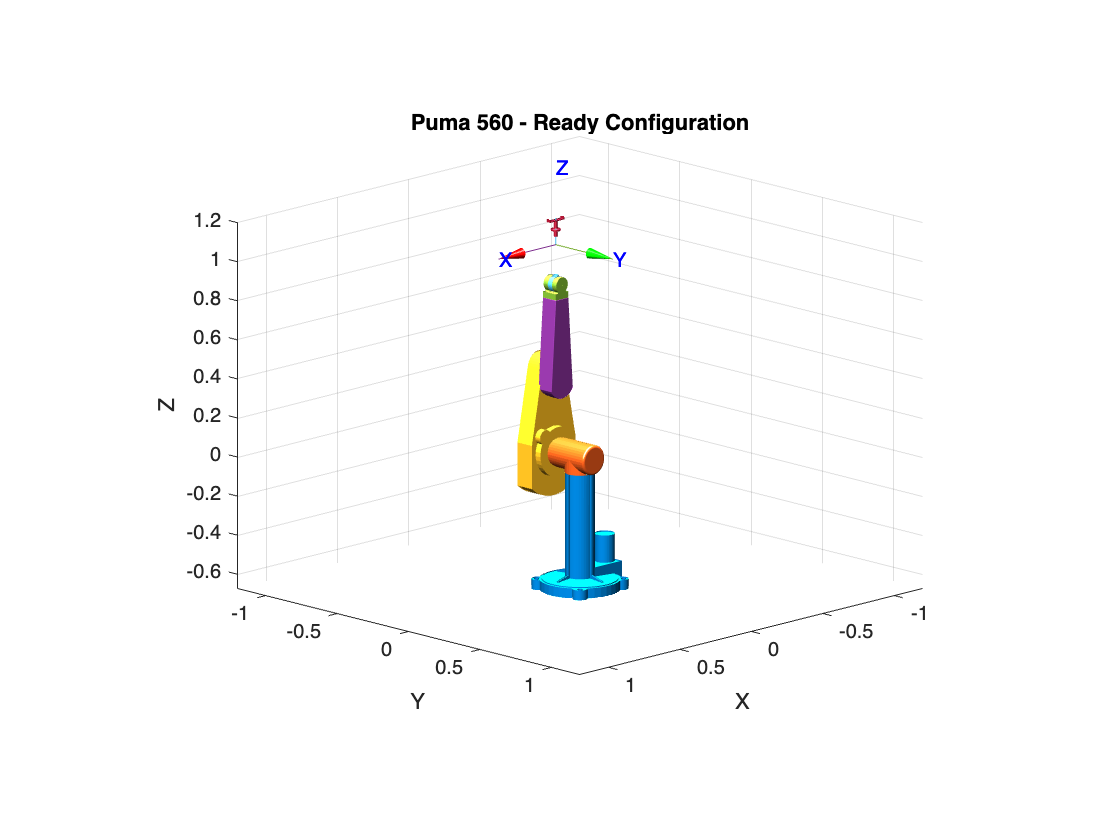

p560.plot3d(qr);  % Visualization for ready configuration
hold on;
title('Puma 560 - Ready Configuration');

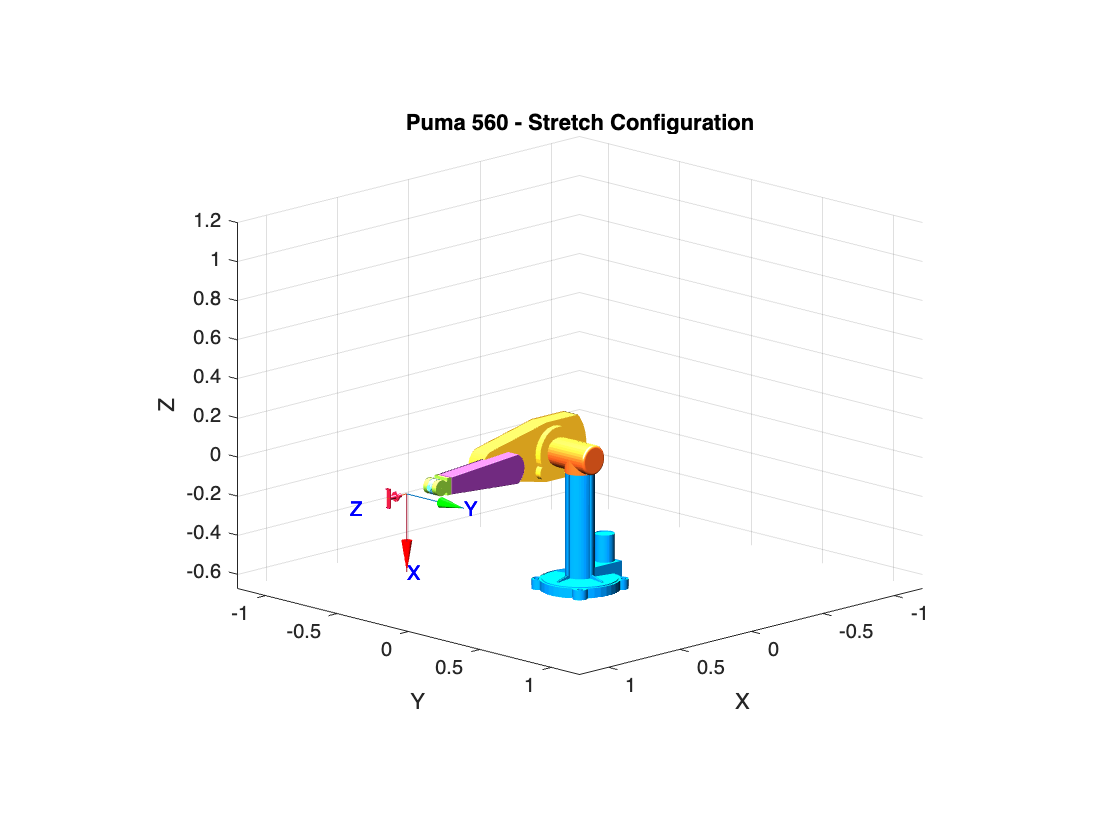

p560.plot3d(qs);  % Visualization for stretch configuration
hold on;
title('Puma 560 - Stretch Configuration');

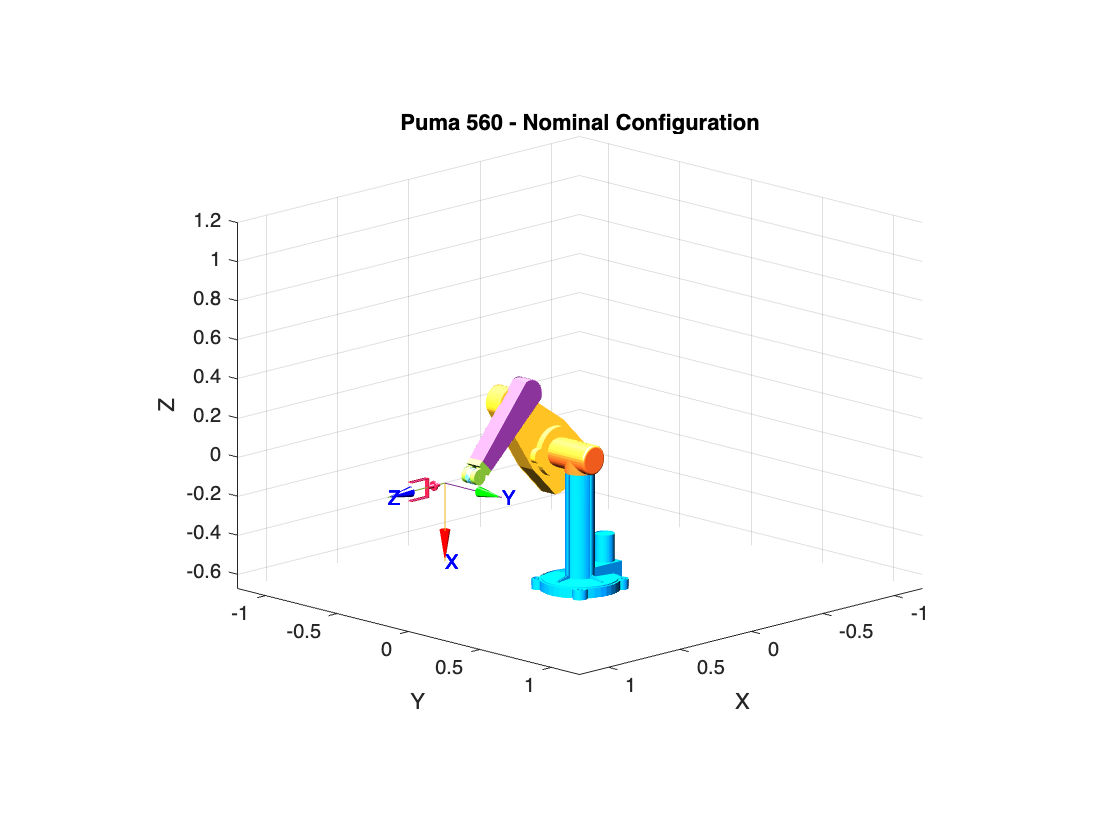

p560.plot3d(qn);  % Visualization for nominal configuration
hold on
title('Puma 560 - Nominal Configuration');

%3.7
p560.tool = SE3();  % Reset tool to no extension

%3.8
T_nominal = p560.fkine(qn);  % Forward kinematics for nominal configuration
q_inv = p560.ikine6s(T_nominal);  % Inverse kinematics

disp('Inverse kinematics joint vector for nominal configuration:');

Inverse kinematics joint vector for nominal configuration:


disp(q_inv);

    2.6486   -3.9270    0.0940    2.5326    0.9743    0.3734



% Step 3.9: Perform inverse kinematics with different arm geometries
q_left_elbow_up = p560.ikine6s(T_nominal, 'lu');  % Left hand, elbow up
q_left_elbow_down = p560.ikine6s(T_nominal, 'ld');  % Left hand, elbow down
q_right_elbow_up = p560.ikine6s(T_nominal, 'ru');  % Right hand, elbow up
q_right_elbow_down = p560.ikine6s(T_nominal, 'rd');  % Right hand, elbow down

% Display the results
disp('Left hand, elbow up:');

Left hand, elbow up:


disp(q_left_elbow_up);

    2.6486   -3.9270    0.0940    2.5326    0.9743    0.3734



disp('Left hand, elbow down:');

Left hand, elbow down:


disp(q_left_elbow_down);

    2.6486   -2.3081    3.1416    0.6743    0.8604    2.6611



disp('Right hand, elbow up:');

Right hand, elbow up:


disp(q_right_elbow_up);

   -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000



disp('Right hand, elbow down:');

Right hand, elbow down:


disp(q_right_elbow_down);

   -0.0000   -0.8335    0.0940   -3.1416    0.8312    3.1416



%3.10
T_unreachable = SE3(10, 10, 10);
q_unreachable = p560.ikine6s(T_unreachable);  % Inverse kinematics for unreachable point

disp('Inverse kinematics result for unreachable point:');

Inverse kinematics result for unreachable point:


disp(q_unreachable);

   NaN   NaN   NaN   NaN   NaN   NaN



Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


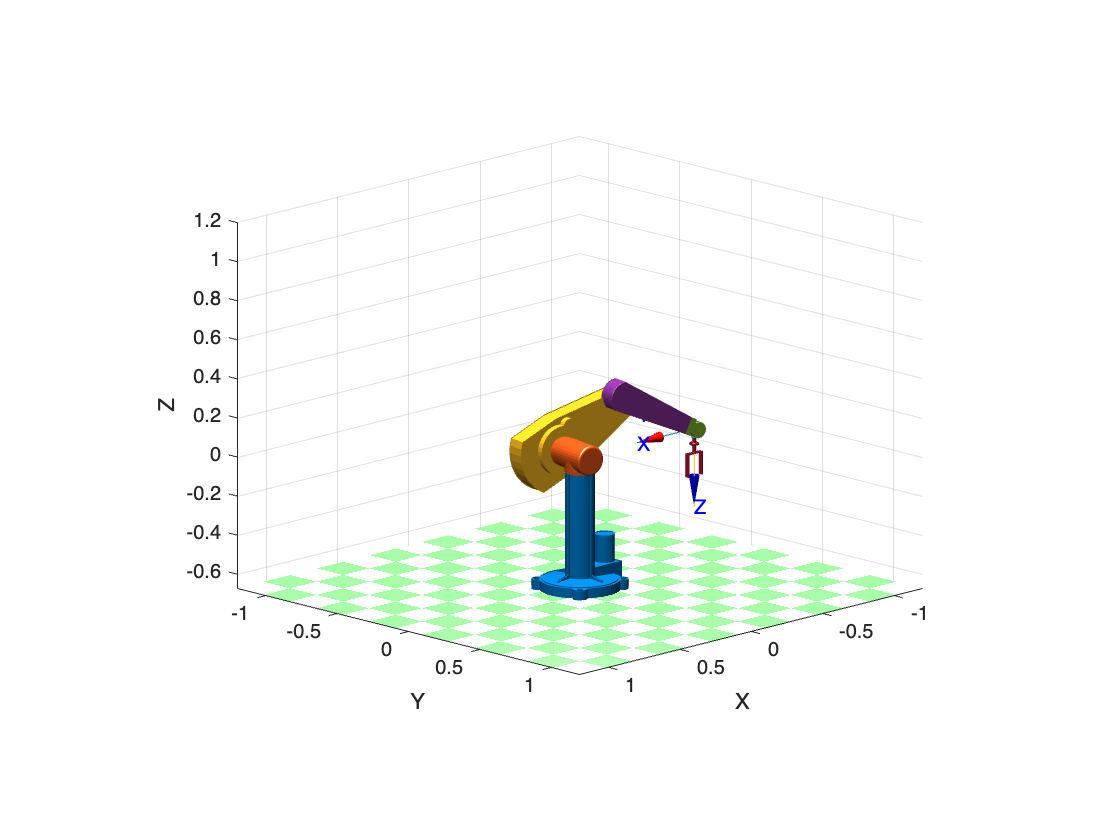

% Step 3.11: Execute the provided code
close all;
clear all;

mdl_puma560;  % Load Puma 560 robot model

T1 = SE3(0.8, 0, 0) * SE3.Ry(pi/2);  % First transformation
T2 = SE3(-0.8, 0, 0) * SE3.Rx(pi);  % Second transformation

q1 = p560.ikine6s(T1);  % Inverse kinematics for T1
q2 = p560.ikine6s(T2);  % Inverse kinematics for T2

t = [0:0.05:2]';  % Time vector for trajectory
q = jtraj(q1, q2, t);  % Joint space trajectory from q1 to q2

p560.plot3d(q);  % Plot the robot motion